# **Pol Nullstellen Kürzung / Pole-Zero Cancellation**

## **Gegeben sei ein stabiles PDT3 System mit einer Nullstelle**

**Given a stable PDT3 system with a zero**

clear all; 
s = tf('s');
G1 = (s + 2)/((s+1)*(s+2)*(s+3));
G1 = zpk(G1)


G1 =
 
        (s+2)
  -----------------
  (s+3) (s+2) (s+1)
 
Continuous-time zero/pole/gain model.



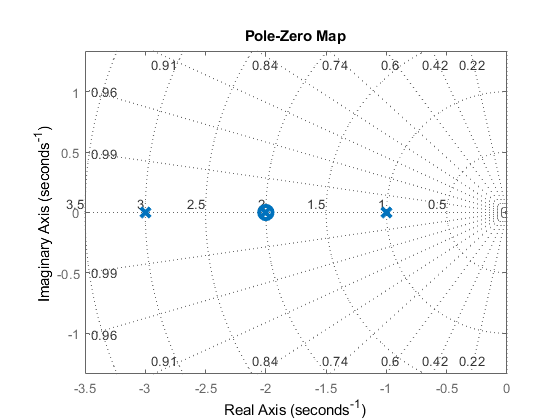

pzmap(G1); grid on; axis equal

%Visuals:
h1 = gca;
h1.Children(1).Children(1).LineWidth =3;
h1.Children(1).Children(1).MarkerSize =10;
h1.Children(1).Children(2).MarkerSize =10;
h1.Children(1).Children(2).LineWidth =3;

## Nach der entsprechenden Kürzung / After cancellation:

G2 = zpk(1/((s+1)*(s+3)))


G2 =
 
       1
  -----------
  (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



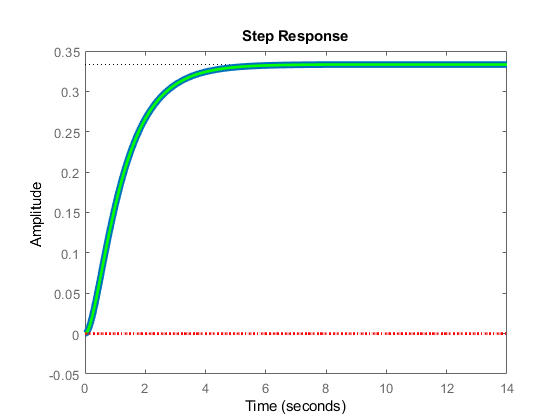

% Sprungantwortvergleich / Step response comparison
step(G1,G2,G1-G2);

% Visuals
h2 = gca; h2.Children(3).Children(2).LineWidth =5;
h2 = gca; h2.Children(2).Children(2).LineWidth =2;
h2 = gca; h2.Children(2).Children(2).Color = [0 1 0];
h2 = gca; h2.Children(1).Children(2).LineWidth =2;
h2 = gca; h2.Children(1).Children(2).Color =[1 0 0];
h2 = gca; h2.Children(1).Children(2).LineStyle = ':';

## Nun sei die Kürzung nicht exakt  / Now the cancellation is not fully achieved 

delta = 0.05;
G3 = zpk((s + 2+ delta)/((s+1)*(s+2)*(s+3)))


G3 =
 
      (s+2.05)
  -----------------
  (s+3) (s+2) (s+1)
 
Continuous-time zero/pole/gain model.



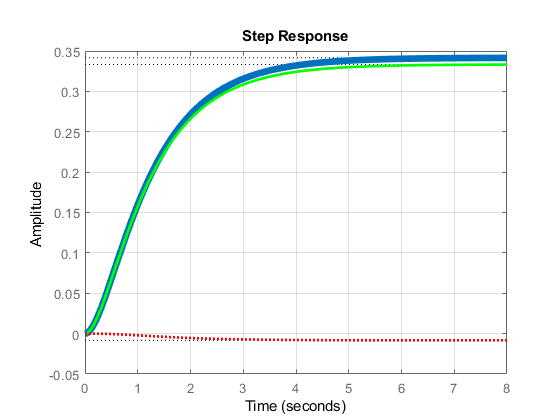

step(G3,G2,G2-G3); grid on;

% Visuals
h2 = gca; h2.Children(3).Children(2).LineWidth =5;
h2 = gca; h2.Children(2).Children(2).LineWidth =2;
h2 = gca; h2.Children(2).Children(2).Color = [0 1 0];
h2 = gca; h2.Children(1).Children(2).LineWidth =2;
h2 = gca; h2.Children(1).Children(2).Color =[1 0 0];
h2 = gca; h2.Children(1).Children(2).LineStyle = ':';

## Gegeben sei ein *instabiles* PT3 System mit einer Nullstelle

Given is an unstable PT3 system with a zero

clear all; 
s = tf('s');
G1 = zpk((s - 2)/((s+1)*(s-2)*(s+3)))


G1 =
 
        (s-2)
  -----------------
  (s-2) (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



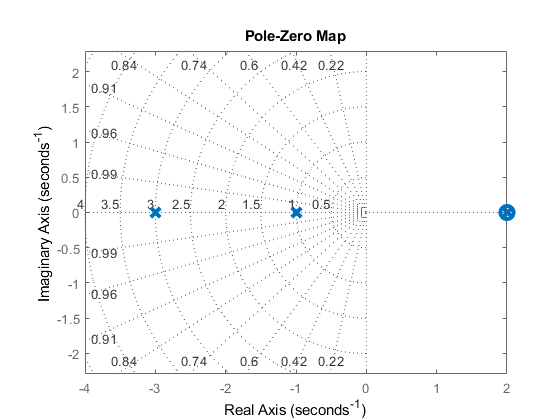

pzmap(G1);grid on; axis equal

% Visuals
h1 = gca;
h1.Children(1).Children(1).LineWidth =3;
h1.Children(1).Children(1).MarkerSize =10;
h1.Children(1).Children(2).MarkerSize =10;
h1.Children(1).Children(2).LineWidth =3;

## Nach der Entsprechenden Kürzung ergibt sich ein *anscheinend* stabiles System:

After the corresponding reduction, an apparently stable system results:

G2 = zpk(1/((s+1)*(s+3)))


G2 =
 
       1
  -----------
  (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



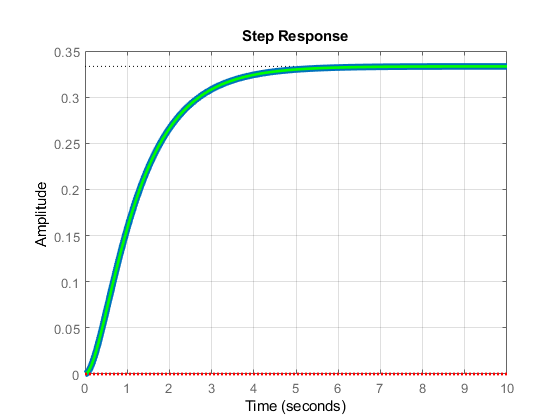

step(G1,G2,G1-G2,10); grid on;

%Visuals
h2 = gca; h2.Children(3).Children(2).LineWidth =5;
h2 = gca; h2.Children(2).Children(2).LineWidth =2;
h2 = gca; h2.Children(2).Children(2).Color = [0 1 0];
h2 = gca; h2.Children(1).Children(2).LineWidth =2;
h2 = gca; h2.Children(1).Children(2).Color =[1 0 0];
h2 = gca; h2.Children(1).Children(2).LineStyle = ':';

## Nun sei die Kürzung nicht exakt / Now the cancellation is not fully achieved:

delta = 0.05;
G3 = zpk((s - 2 + delta)/((s+1)*(s-2)*(s+3)))


G3 =
 
      (s-1.95)
  -----------------
  (s-2) (s+3) (s+1)
 
Continuous-time zero/pole/gain model.



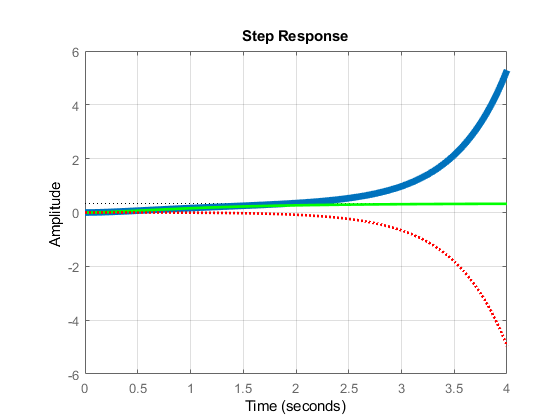

step(G3,G2,G2-G3,4); grid on

%Visuals:
h2 = gca; h2.Children(3).Children(2).LineWidth =5;
h2 = gca; h2.Children(2).Children(2).LineWidth =2;
h2 = gca; h2.Children(2).Children(2).Color = [0 1 0];
h2 = gca; h2.Children(1).Children(2).LineWidth =2;
h2 = gca; h2.Children(1).Children(2).Color =[1 0 0];
h2 = gca; h2.Children(1).Children(2).LineStyle = ':';

# Daher: INSTABILE POLE NIEMALS KÜRZEN ODER KOMPENSIEREN!

# Therefore: NEVER EVER CANCEL OR COMPENSATIVE UNSTABLE POLES!